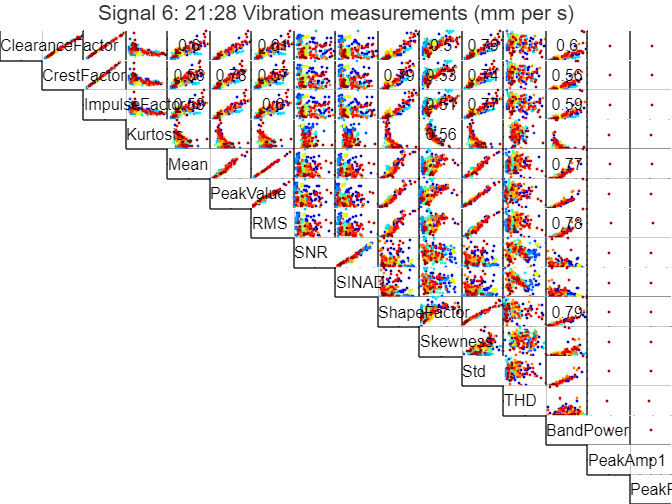

Features = DFD_FeatureTable_TimeDomain;
SignalNames = signalNames_Time;
FeatureNames = featureNames_Time;
lowerR2 = 0.3;
upperR2 = 0.8;
signalNum = 6; % 21:28 Vibration measurements (mm per s)
R2 = fnPlotFeatureVsFeature_Array(featureArray, lowerR2, upperR2, signalNum, combinedFeatureNames, sensorNames);

% Print the table of R2 values verse every other signal
disp(num2str(R2, '%.2f  '));

0.00  1.00  1.00  0.22  0.60  0.82  0.61  0.02  0.01  0.84  0.50  0.79  0.04  0.60   NaN   NaN
0.00  0.00  1.00  0.21  0.56  0.78  0.57  0.02  0.01  0.79  0.53  0.74  0.04  0.56   NaN   NaN
0.00  0.00  0.00  0.22  0.58  0.80  0.60  0.02  0.01  0.82  0.51  0.77  0.04  0.59   NaN   NaN
0.00  0.00  0.00  0.00  0.06  0.12  0.06  0.01  0.01  0.21  0.56  0.17  0.02  0.10   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.93  1.00  0.04  0.03  0.80  0.06  0.91  0.02  0.77   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.94  0.03  0.02  0.92  0.19  0.97  0.03  0.82   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.04  0.03  0.82  0.06  0.92  0.02  0.78   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.96  0.02  0.00  0.02  0.00  0.02   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.01  0.00  0.01  0.00  0.01   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.25  0.97  0.01  0.79   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.

fs = 1 / Ts; % Sampling frequency
selectedFeature = 1;
selectedFeatureArray = [selectedFeature]; % Array of correlated features
for i = 1:numOfCombinedFeatures + 1 - selectedFeature
    if R2(i,selectedFeature) > lowerR2 && R2(i,selectedFeature) < upperR2
        selectedFeatureArray = [selectedFeatureArray i];
    end
end
for i = selectedFeature + 1:numOfCombinedFeatures
    if R2(selectedFeature,i) > lowerR2 && R2(selectedFeature,i) < upperR2
        selectedFeatureArray = [selectedFeatureArray i];
    end
end
selectedFeatureArray = sort(selectedFeatureArray);
numOfSelectedFeatures = size(selectedFeatureArray, 2);
selectedFeatureData = {numOfSelectedFeatures};

for i = 1:numOfSelectedFeatures
    selectedFeatureData{i} = featureArray(:, i, signalNum);
end

disp(selectedFeatureArray);

     1     5     7    11    12    14



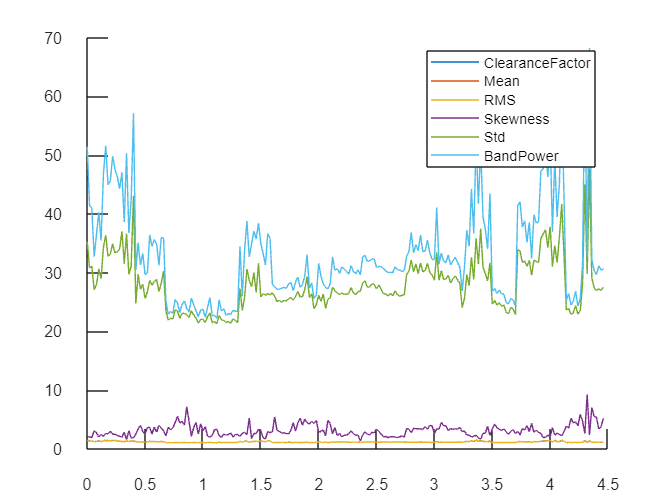

% Plot the identified signals for the Mean of each signal
n = size(selectedFeatureData{1}, 1); % Sample , 10
t = ( 0 : 1/fs : (n / fs) - 1/fs)';
figure(); hold on;
leg = {numOfSelectedFeatures};
for signalIndex = 1:numOfSelectedFeatures
    plot(t, selectedFeatureData{signalIndex});
    txtTemp = char(combinedFeatureNames(selectedFeatureArray(signalIndex)));
    leg{signalIndex} = char(txtTemp);
end
legend(leg);

X_signals = zeros(n, numOfSelectedFeatures);
for index = 1:numOfSelectedFeatures
    X_signals(:,index) = selectedFeatureData{index}; 
end

X1 = X_signals(:,1);
X2 = X_signals(:,2);
X3 = X_signals(:,3);
X4 = X_signals(:,4);
X5 = X_signals(:,5);
X6 = X_signals(:,6);

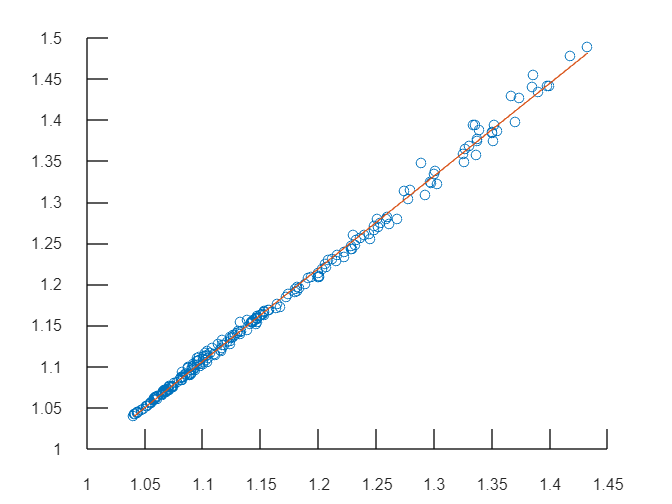

FIT = 94.367057

fnPlotModel(X1, X2);

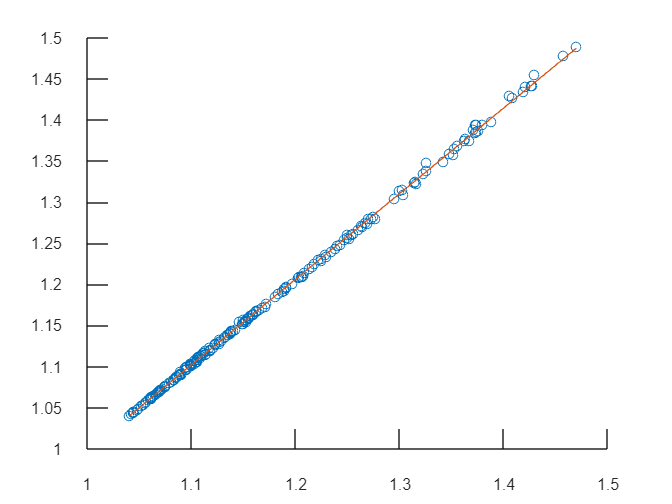

FIT = 98.031972

fnPlotModel(X1, X3);

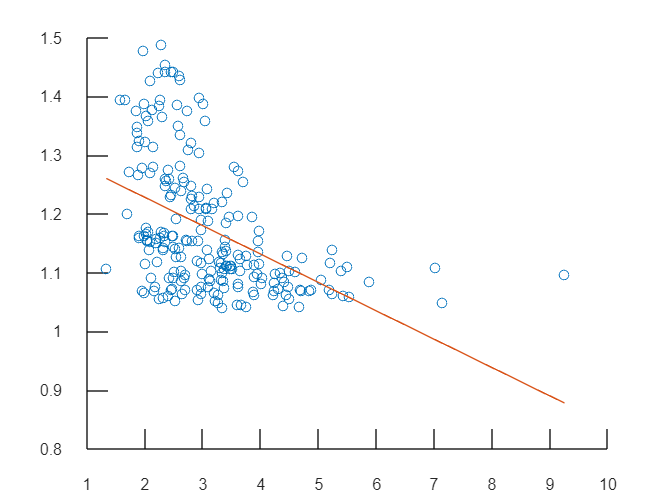

FIT = 11.492873

fnPlotModel(X1, X4);

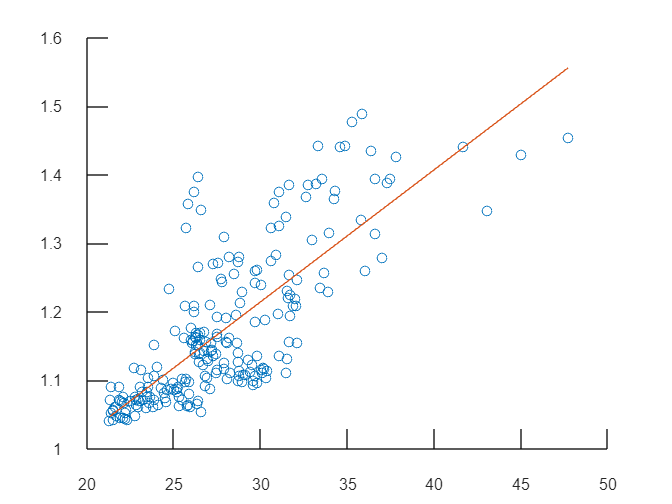

FIT = 36.475904

fnPlotModel(X1, X5);

% Multivariate Model candidate 1
X = [ones(n,1) X_2 X_3];
Y = X_1;
k = size(X, 2) - 1; % Number of parameters for model
beta = inv(X' * X) * (X' * Y);

Y_est = X * beta;
RSS = sum((Y_est - Y).^2);
RSS = var(Y_est - Y) / var(Y);

% Fit equation from compare function
FIT = 100 * (1-norm(Y-Y_est)/norm(Y-mean(Y)))

FIT = 99.5811

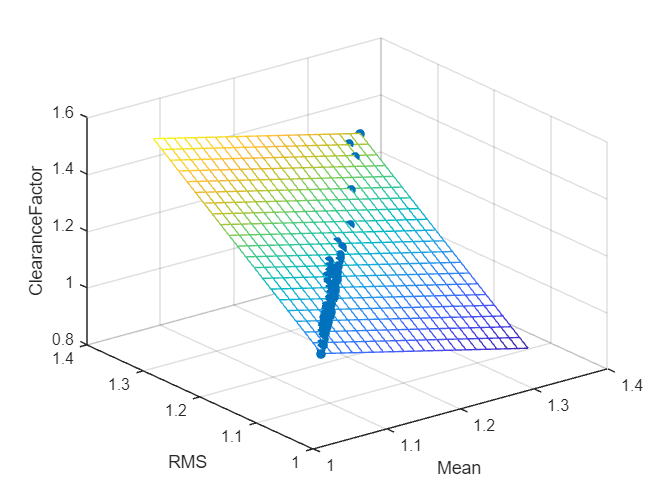

fnScatterPlot(X(:,2), X(:,3), Y, beta, FeatureNames(selectedFeatureArray(2)), FeatureNames(selectedFeatureArray(3)), FeatureNames(selectedFeatureArray(1)));

% Multivariate Model candidate 2
X = [ones(n,1) X_2 X_3];
Y = X_1;
k = size(X, 2) - 1; 
beta = inv(X' * X) * (X' * Y);

Y_est = X * beta;
RSS = sum((Y_est - Y).^2);
RSS = var(Y_est - Y) / var(Y);

% Fit equation from compare function
FIT = 100 * (1-norm(Y-Y_est)/norm(Y-mean(Y)))

FIT = 99.5811

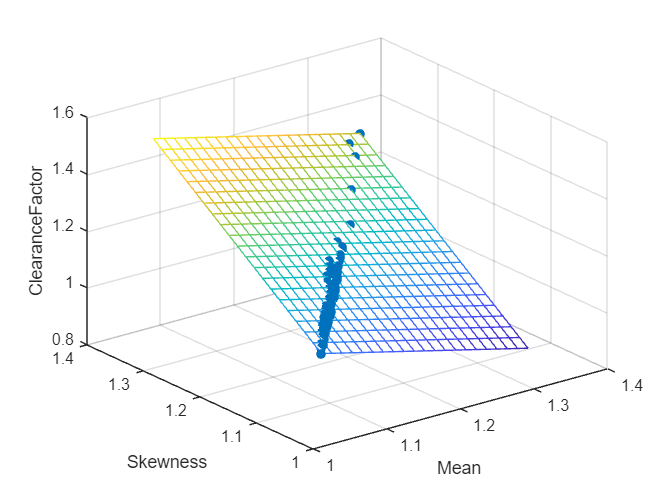

fnScatterPlot(X(:,2), X(:,3), Y, beta, FeatureNames(selectedFeatureArray(2)), FeatureNames(selectedFeatureArray(4)), FeatureNames(selectedFeatureArray(1)));

% Multivariate Model candidate 3
X = [ones(n,1) X_3 X_4];
Y = X_1;
k = size(X, 2) - 1; 
beta = inv(X' * X) * (X' * Y);

Y_est = X * beta;
RSS = sum((Y_est - Y).^2);
RSS = var(Y_est - Y) / var(Y);

% Fit equation from compare function
FIT = 100 * (1-norm(Y-Y_est)/norm(Y-mean(Y)))

FIT = 95.6333

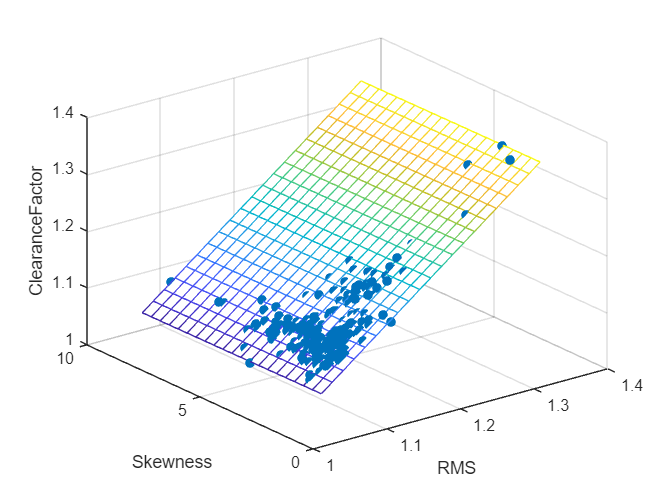

fnScatterPlot(X(:,2), X(:,3), Y, beta, FeatureNames(selectedFeatureArray(3)), FeatureNames(selectedFeatureArray(4)), FeatureNames(selectedFeatureArray(1)));

% Multivariate Model candidate 3
X = [ones(n,1) X_3 X_4];
Y = X_1;
k = size(X, 2) - 1; 
beta = inv(X' * X) * (X' * Y);

Y_est = X * beta;
RSS = sum((Y_est - Y).^2);
RSS = var(Y_est - Y) / var(Y);

% Fit equation from compare function
FIT = 100 * (1-norm(Y-Y_est)/norm(Y-mean(Y)))

FIT = 95.6333

fnScatterPlot(X(:,2), X(:,3), Y, beta, FeatureNames(selectedFeatureArray(3)), FeatureNames(selectedFeatureArray(4)), FeatureNames(selectedFeatureArray(1)));

X = [ones(n,1) X_2 X_2.*X_2]; % Non linear fitting?
Y = X_1;
beta = inv(X' * X) * (X' * Y)

beta =     0.3323
    0.3840
    0.2926



Y_est = X * beta;
RSS = sum((Y_est - Y).^2);
RSS = var(Y_est - Y) / var(Y);

% Fit equation from compare function
FIT = 100 * (1-norm(Y-Y_est)/norm(Y-mean(Y)))

FIT = 88.4104

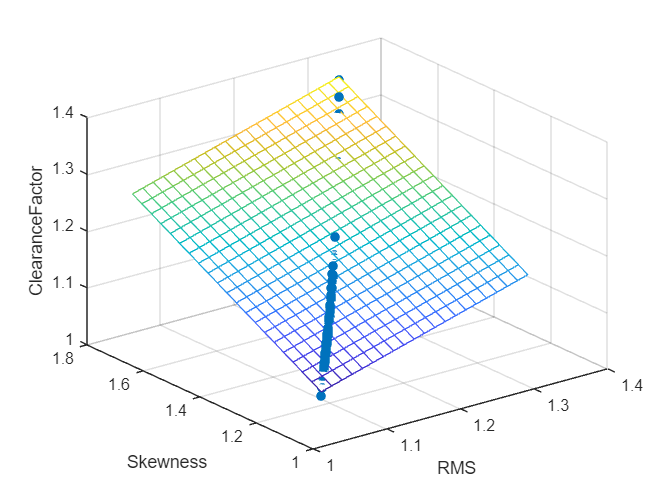

fnScatterPlot(X(:,2), X(:,3), Y, beta, FeatureNames(selectedFeatureArray(3)), FeatureNames(selectedFeatureArray(4)), FeatureNames(selectedFeatureArray(1)));

% From Matlab AIC function
%    'nAIC': Normalized Akaike's Information Criterion (default)
%            nAIC = log(det(E'*E/N)) + 2d/N
%     'AIC': Akaike's Information Criterion (raw measure)
%            AIC = N*nAIC + N*(ny*log(2*pi) + 1)
AIC(1) = -2*(log(RSS)) + 2*k;
AIC2(1) = 2 * k + n * log (RSS / n); % Which is the better equation?

% An alternative formula for least squares regression type analyses 
% for normally distributed errors:
% https://www.statisticshowto.com/akaikes-information-criterion/
deltaAIC(1) = 2 * k + n * log(RSS);

function [] = fnScatterPlot(X1, X2, Y, beta, labelX1, labelX2, labelY)
    figure();
    title("Model Candidate 4");
    scatter3(X1,X2,Y,'filled');
    hold on;
    interval1 = (max(X1) - min(X1))/20;
    x1fit = min(X1):interval1:max(X1);
    interval2 = (max(X2) - min(X2))/20;
    x2fit = min(X2):interval2:max(X2);
    [X1FIT,X2FIT] = meshgrid(x1fit, x2fit);
    %YFIT = b(1) + b(2)*X1FIT + b(3)*X2FIT + b(4)*X1FIT.*X2FIT;
    YFIT = beta(1) + beta(2).*X1FIT + beta(3).*X2FIT;
    mesh(X1FIT, X2FIT, YFIT);
    xlabel(labelX1, 'Interpreter', 'none');
    ylabel(labelX2, 'Interpreter', 'none');
    zlabel(labelY, 'Interpreter', 'none');
end